## Sound 불러오기

[y, Fs] = audioread('Sample2.wav');
info = audioinfo('Sample2.wav');

t = 0:seconds(1/Fs):seconds(info.Duration);
t = t(1:end-1);

## Sound Plotting

%원래의 Sound plotting
figure(1);
subplot(211);
plot(t,y);
title('Original Sound');
xlabel('Time');
ylabel('Audio Signal');

%1차 LPF를 통과한 signal yl생성
a = [1 -0.75]; b = 0.25;
yl = filter(b, a, y); %Filter 함수 중요!


$$y\left\lbrack n\right\rbrack =0\ldotp 8x\left\lbrack n\right\rbrack -0\ldotp 8y\left\lbrack n-1\right\rbrack$$


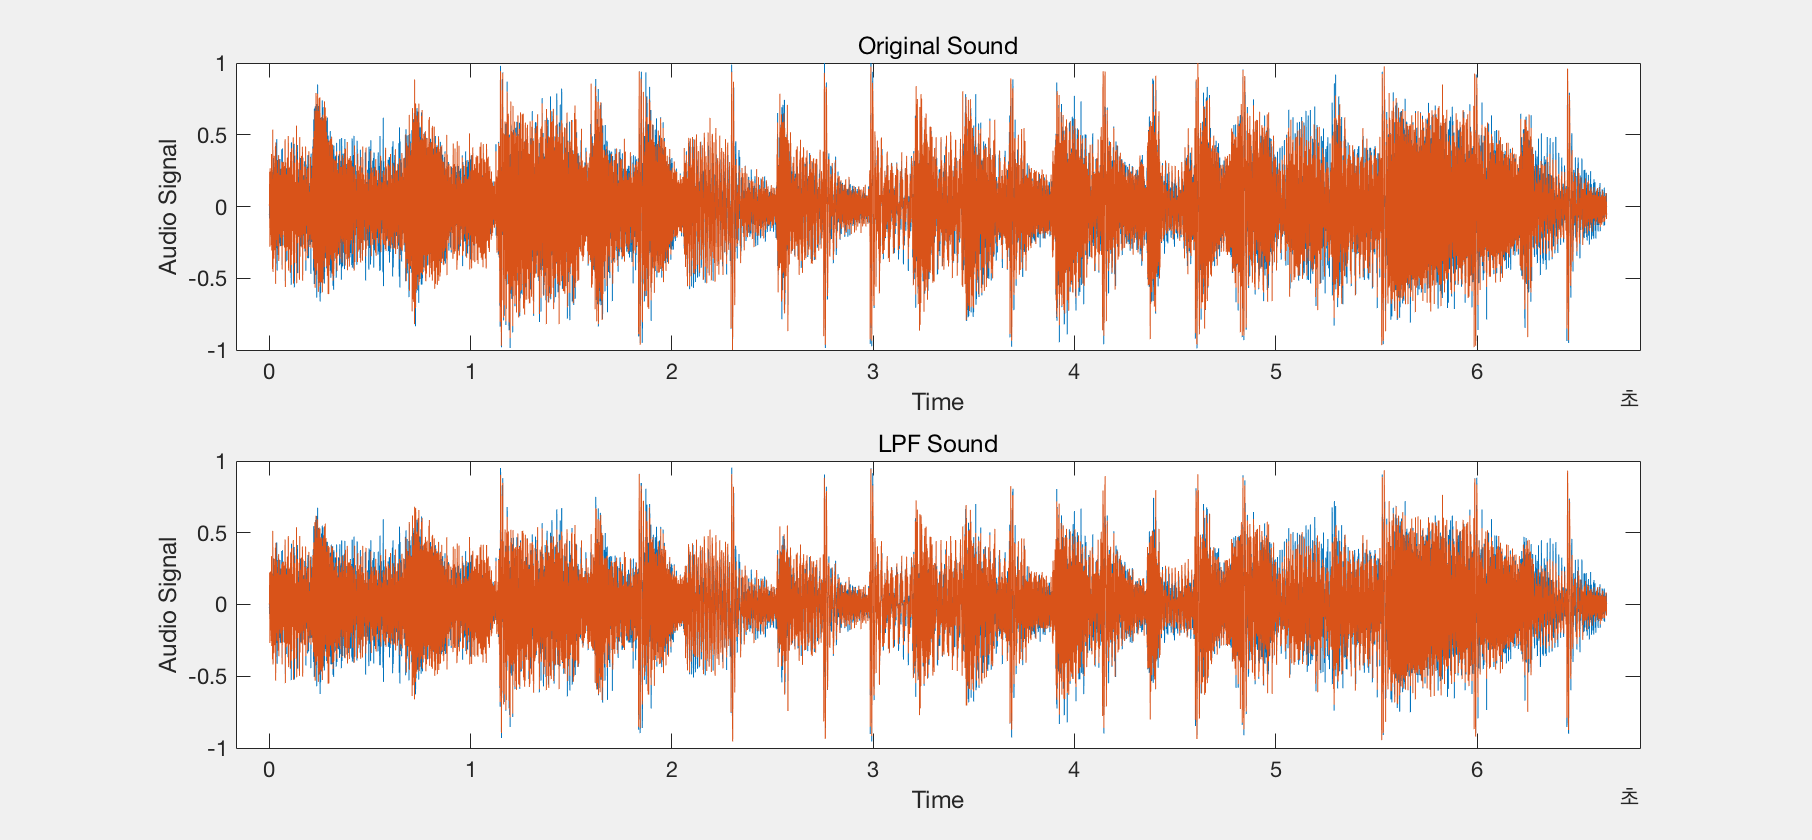

subplot(212);
plot(t,yl); %%LPF를 통과한 Signal의 Plotting
title('LPF Sound');
xlabel('Time');
ylabel('Audio Signal');

hold off;

## Fourier Transform을 통한 주파수 분석

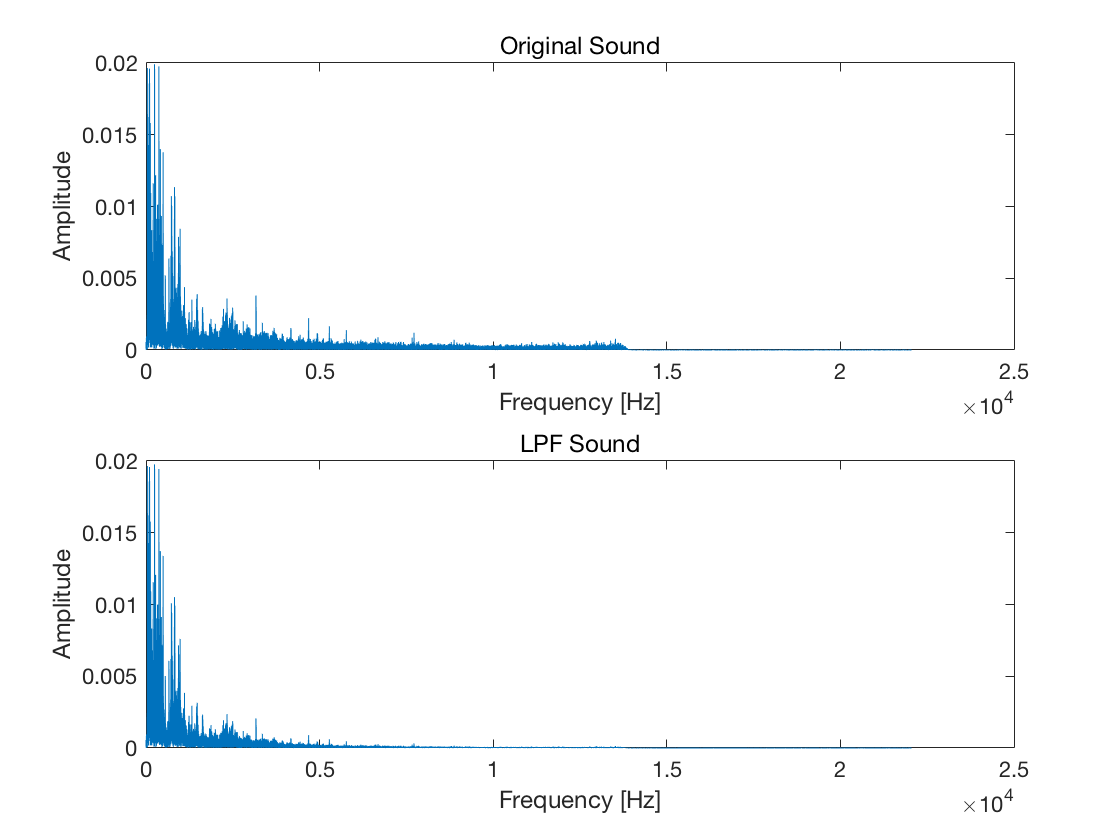

%원래의 Signal
Y = fft(y);

P2 = abs(Y/length(t));
P1 = P2(1:length(t)/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:length(t)/2)/length(t);

figure(2);
subplot(211); plot(f,P1);
title('Original Sound');
xlabel('Frequency [Hz]');
ylabel('Amplitude');

%LPF를 통과시킨 Signal
Yl = fft(yl);
P2l = abs(Yl/length(t));
P1l = P2l(1:length(t)/2+1);
P1l(2:end-1) = 2*P1l(2:end-1);

subplot(212); plot(f,P1l);
title('LPF Sound');
xlabel('Frequency [Hz]');
ylabel('Amplitude');

Tip> 복구시키고 싶다며는

%%yh = ifft(Yh,length(y),'symmetric');